# SLCO4A - Aula Prática 9

## Propriedades da série de Fourier

### Linearidade

Suponha que os coeficientes da série de Fourier exponencial complexa dos sinais periódicos $x\left(t\right)$ e $y\left(t\right)$sejam denotados por $a_k$ e $b_k$, respectivamente. Além disto $z_1$e $z_2$ denotam dois números complexos. Então,


$$z_1 x\left(t\right)+z_2 y\left(t\right)\leftrightarrow z_1 a_k +z_2 b_k$$


**Exercício 1:**     Considere os sinais periódicos $x\left(t\right)=\cos \left(t\right)$e $y\left(t\right)=\textrm{sen}\left(2t\right)$e os escalares $z_1 =3+2i$ e $z_2 =2$. Considere 11 termos para o cômputo da série de Fourier.

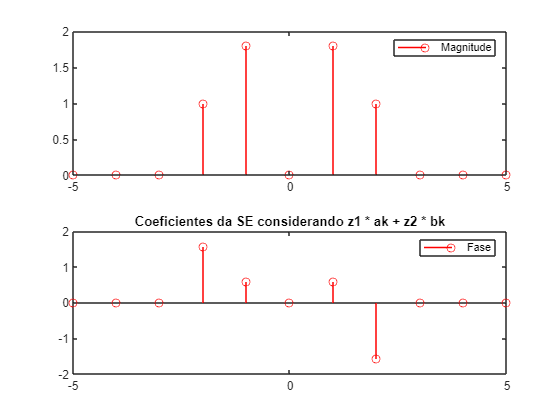

t0 = 0;
T = 2*pi;
w = 2*pi/T;
syms t
z1 = 3 + 2*i;
z2 = 2;
x = cos(t);
y = sin(2*t);

f = z1*x + z2*y;

k = -5:5;
%Coeficientes da SF 
left = 1/T*int(f *exp(-j*k*w*t), t, t0, t0+T);
left = eval(left);

figure 
subplot(211)
stem(k, abs(left));
legend("Magnitude")
subplot(212)
stem(k, angle(left));
legend("Fase")

%z1*ak+z2*bk
a = 1/T * int(x*exp(-j*k*w*t), t , t0, t0+T);
b = 1/T * int(y*exp(-j*k*w*t), t , t0, t0+T);
right = z1 * a + z2 * b;
right = eval(right);
subplot(211)
stem(k, abs(right), 'r')
legend("Magnitude")
subplot(212)
stem(k, angle(right), 'r')
legend("Fase")
title("Coeficientes da SE considerando z1 * ak + z2 * bk")

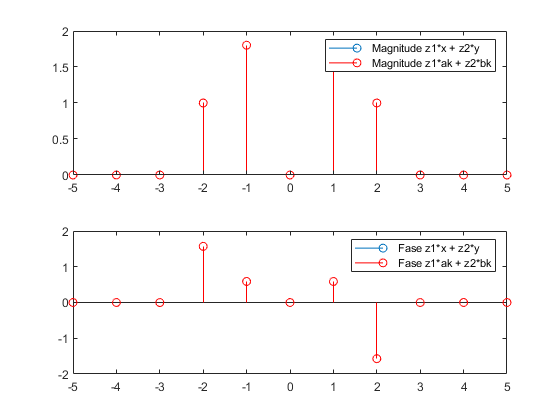


figure 
subplot(211)
stem(k, abs(left));
hold on
stem(k, abs(right), 'r')
legend("Magnitude z1*x + z2*y", "Magnitude z1*ak + z2*bk")
subplot(212)
stem(k, angle(left));
hold on 
stem(k, angle(right), 'r')
legend("Fase z1*x + z2*y", "Fase z1*ak + z2*bk")

### Deslocamento temporal

Um deslocamento temporal de um sinal periódico resulta em uma mudança de fase dos coeficientes da série de Fourier. Então se $x\left(t\right)\leftrightarrow a_k$, a relação de deslocamento temporal resulta em 


$$x\left(t-t_1 \right)\leftrightarrow e^{-\textrm{jk}\omega_0 t_1 } a_k$$


**Exercício 2: **Considere o sinal periódico $x\left(t\right)={\textrm{te}}^{-5t}$, $0\le t\le 10$. Além disto, considere $t_1 =3$. Consequentemente, o sinal $x\left(t-t_1 \right)$é dado por $x\left(t-t_1 \right)=x\left(t-3\right)=\left(t-3\right)e^{-5\left(t-3\right)}$. Considere 11 termos para o cômputo da série de Fourier.

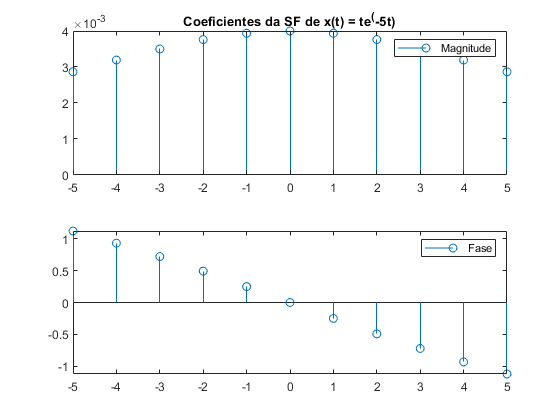

t0 = 0;
T = 10;
w = 2*pi/T;
syms t 
x = t*exp(-5*t);
k = -5:5;
a = 1/T * int(x*exp(-j*k*w*t), t, t0, t0+T);
a1 = eval(a);
figure
subplot(211)
stem(k, abs(a1))
legend("Magnitude")
title("Coeficientes da SF de x(t) = te^(-5t)")
subplot(212)
stem(k, angle(a1))
legend('Fase')

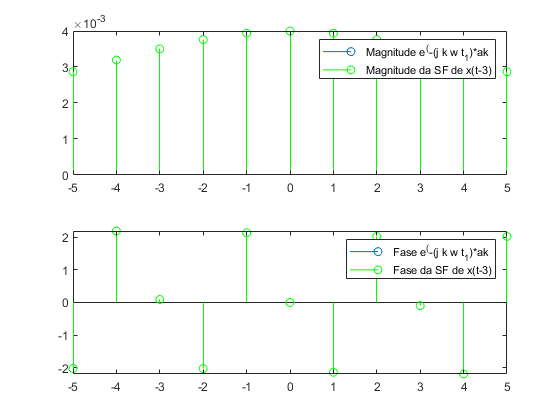

% Coeficientes da SF da função deslocada a partir e^(-jkwt1)*ak
t1 = 3;
right = exp(-j*k*w*t1).*a;
%Transformando para numerico 
right = eval(right);
figure 
subplot(211)
stem(k, abs(right))
hold on
%legend("Magnitude")
%title("Coeficientes considerando e^(-(j k w t_1)) * ak")
subplot(212)
stem(k, angle(right))
hold on 
%legend("Fase")
%Coeficientes da serie de fourier a partir da função deslocada x(t-3)=
%(t-3)*e^(-5*(t-3))

x = (t-t1) .* exp(-5*(t-t1));
a = 1/T * int(x*exp(-j*k*w*t), t, t0+t1, t0+T+t1);
coe = eval(a);
subplot(211)
stem(k, abs(coe), 'g')
legend("Magnitude e^(-(j k w t_1)*ak", 'Magnitude da SF de x(t-3)')
subplot(212)
stem(k, angle(coe), 'g')
legend("Fase e^(-(j k w t_1)*ak", 'Fase da SF de x(t-3)')

### Reversão temporal

Se $x\left(t\right)\leftrightarrow a_k$, a expressão matemática é


$$x\left(-t\right)\leftrightarrow a_{-k}$$


**Exercício 3: **Considere um sinal periódico dado por $x\left(t\right)=t\;\cos \left(t\right),$$0\le t\le 2\pi \ldotp$ Considere 11 termos para o cômputo da série de Fourier.

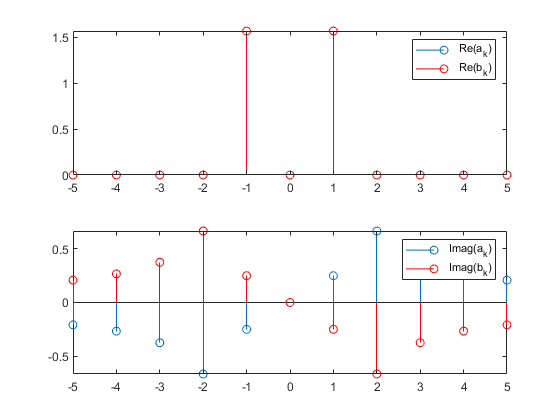

t0 = 0;
T = 2*pi;
w = 2*pi/T;
syms t 
x = t * cos(t);
k = -5:5;
a = 1/T * int(x*exp(-j*k*w*t), t, t0, t0+T);
ak = eval(a);
figure 
subplot(211)
stem(k, real(ak))
hold on
subplot(212)
stem(k, imag(ak))
hold on 


%Calculo da reversão temporal 
x_ = -t * cos(-t);
b = 1/T * int(x_*exp(-j*k*w*t), t, t0-T, t0);
bk = eval(b);
subplot(211)
stem(k, real(bk), 'r');
legend("Re(a_k)", "Re(b_k)")
subplot(212)
stem(k, imag(bk), 'r');
legend("Imag(a_k)", "Imag(b_k)")

### Escalonamento temporal

Os coeficientes da série de Fourier de uma versão escalonada $x\left(\lambda \;t\right)$ de $x\left(t\right)$não muda, exceto o período fundamental da versão escalonada que torna-se $\frac{T}{\lambda \;}$ e o período fundamental torna-se $\lambda \;\omega_0$.


$$x\left(\lambda \;t\right)\leftrightarrow a_k$$


**Exercício 4: **Considere um sinal periódico dado por $x\left(t\right)=t\;\cos \left(t\right),$$0\le t\le 2\pi \ldotp$ Efetue um escalonamento $\lambda =2$. Considere 11 termos para o cômputo da série de Fourier.

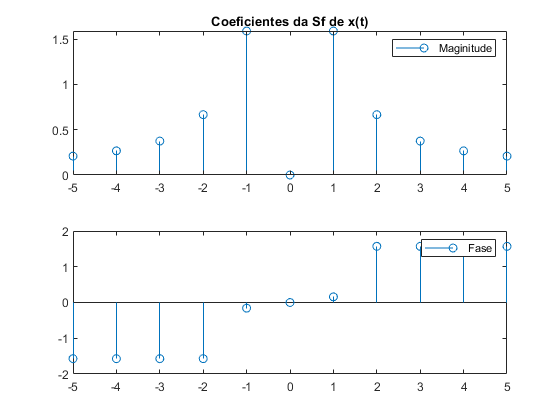

syms t 
t0 = 0;
T = 2*pi;
w = 2*pi/T;
x = t * cos(t);
k = -5:5;
a = 1/T * int(x*exp(-j*k*w*t), t, t0, t0+ T);
a1 = eval(a);
figure 
subplot(211)
stem(k, abs(a1));
legend("Maginitude")
title("Coeficientes da Sf de x(t)")
subplot(212)
stem(k, angle(a1))
legend('Fase')

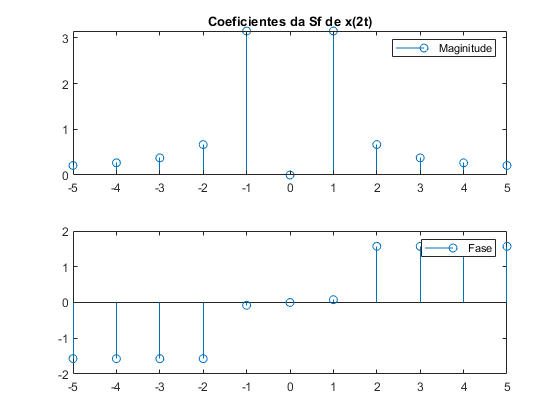


%Escalonamento da função x(2t)
lambda = 2;
w = 2*pi*lambda/T;
x = lambda * t * cos(lambda*t);
a = 1/T * int(x*exp(-j*k*w*t), t, t0, t0+ T);
a1 = eval(a);
figure 
subplot(211)
stem(k, abs(a1));
legend("Maginitude")
title("Coeficientes da Sf de x(2t)")
subplot(212)
stem(k, angle(a1))
legend('Fase')

### Multiplicação de sinais

Os coeficientes da série de Fourier do produto de dois sinais é igual a convolução dos coeficientes da Série de Fourier de cada sinal. Suponha que $x\left(t\right)\leftrightarrow a_k$ e $y\left(t\right)\leftrightarrow b_k$. Então,


$$x\left(t\right)y\left(t\right)\leftrightarrow a_k *b_k$$


**Exercício 5: **Considere os sinais periódicos dados por $x\left(t\right)=\cos \left(t\right)$e $y\left(t\right)=\textrm{sen}\left(t\right)$, $0\le t\le 2\pi \ldotp$ Avalie os coeficientes do produto $z\left(t\right)=x\left(t\right)y\left(t\right)$. Considere 11 termos para o cômputo da série de Fourier de $x\left(t\right)$e $y\left(t\right)$.

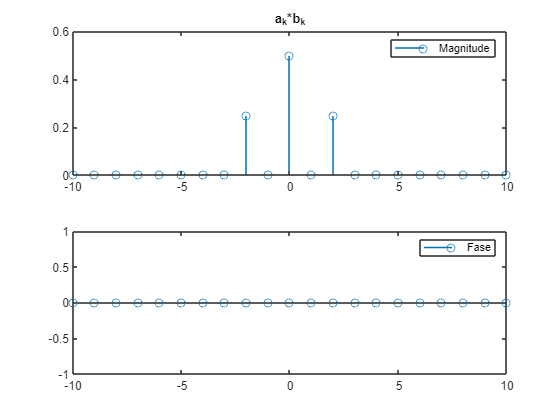

t0 = 0;
T = 2*pi;
w = 2*pi/T;
syms t 
x = cos(t);
k = -5:5;
a = 1/T * int(x*exp(-j*k*w*t), t, t0, t0+T); %coef. SF cos(t)
ak = eval(a);
y = sin(t);
k = -5:5;
b = 1/T * int(y*exp(-j*k*w*t), t, t0, t0+T); %coef. SF sin(t)
bk = eval(a);

%Calculo dos coef. z(t) => coef. conv ak*bk
r = conv(ak, bk);
figure
subplot(211)
stem(-10:10,abs(r))
legend("Magnitude")
title("a_k*b_k")
subplot(212)
stem(-10:10, angle(r))
legend("Fase")

%Coef z(t) = x(t) * y(t)
z = x*y;
k = -5:5;
a = 1/T * int(z*exp(-j*k*w*t), t, t0, t0+T); %coef. SF cos(t)
ak = eval(a);

### Simetria

#### Simetria par

Na representação trigonométrica 

$x\left(t\right)=a_0 +\sum_{n=1}^{\infty } b_n \cos \left(n\omega_0 t\right)+\sum_{n=1}^{\infty } c_n \textrm{sen}\left(n\omega_0 t\right)$, $t\in \left\lbrack t_0 ,t_0 +T\right\rbrack$

onde os coeficientes da série de Fourier na forma trigonométrica são dados por


$$a_0 =\frac{1}{T}\int_{t_0 }^{t_0 +T} x\left(t\right)\textrm{dt}$$



$$b_n =\frac{2}{T}\int_{t_0 }^{t_0 +T} x\left(t\right)\cos \left(n\omega_0 t\right)\textrm{dt}$$



$${\;c}_n =\frac{2}{T}\int_{t_0 }^{t_0 +T} x\left(t\right)\textrm{sen}\left(n\omega_0 t\right)\textrm{dt}$$


Se um sinal $x\left(t\right)=x\left(-t\right)$é par, então, $c_n =0$.

E da representação por série de Fourier complexa obtém-se que $a_k =a_{-k}$.

**Exercício 6: **Considere o sinal periódico e com simetria par dado por $x\left(t\right)=t^2$, $-2\le t\le 2\ldotp$ Avalie os coeficientes da série de Fourier para 11 termos.

#### Simetria ímpar

Se um sinal $x\left(t\right)=-x\left(-t\right)$é impar, então, $b_n =0$.

E da representação por série de Fourier complexa obtém-se que $a_k =-a_{-k}$.

**Exercício 7: **Considere o sinal periódico e com simetria ímpar dado por $x\left(t\right)=t$, $-2\le t\le 2\ldotp$ Avalie os coeficientes da série de Fourier para 11 termos.

## Identidade de Parseval

A potência média de um sinal periódico $x\left(t\right)$ com período $T$ é igual a soma dos quadrados dos coeficientes da série de Fourier da forma exponencial complexa. A expressão matemática é


$$P_x =\frac{1}{T}\int_T {\left|x\left(t\right)\right|}^2 \;\textrm{dt}=\sum_{k=-\infty }^{\infty } {\left|a_k \right|}^2$$


Se o sinal for real,


$$P_x =\frac{1}{T}\int_T {\left|x\left(t\right)\right|}^2 \;\textrm{dt}=a_0 +2\sum_{k=1}^{\infty } {\left|a_k \right|}^2$$


**Exercício 8: **Considere o sinal periódico $x\left(t\right)=\textrm{sen}\left(t\right)$, $0\le t\le 2\pi \;\ldotp$ Avalie os coeficientes da série de Fourier para 13 termos.

t0 = 0;
T = 2*pi;
x = sin(t);
P = 1/T * int(abs(x)^2, t, t0, t0+T);
Px = eval(P)

Px = 0.5000

%Calculo pela SF
w = 2*pi/T;
k = -6:6;
a = 1/T*int(x*exp(-j*k*w*t), t, t0, t0+T);
eval(a);
Pp = sum(abs(a).^2);
eval(Pp)

ans = 0.5000

## Critério de aproximação de sinais por série de Fourier

Um critério de "qualidade" de uma aproximação de representação de função por meio de série de Fourier é por meio do valor percentual de potência média que $2K+1$ componentes dos termos de uma série de Fourier correspondem.

A expressão do percentual de aproximação é 


$$\left(\sum_{n=-K}^K \frac{{\left|a_n \right|}^{2\;} }{P_x }\right)100%$$


**Exercício 9: **Considere o sinal periódico $x\left(t\right)=t^3$, $-1\le t\le 1\;\ldotp$ Avalie os coeficientes da série de Fourier para a seguinte quantidade de termos: 7, 41, 101, bem como o percentual de aproximação das funções, respectivamente.

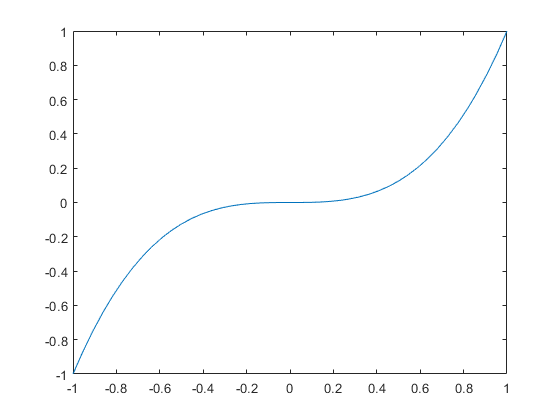

syms t
x = t^3;
t0 = -1;
T = 2;
w = 2*pi/T;
figure
fplot(x, [-1 1])

Px = 1/T * int(abs(x)^2, t, t0, t0+T);
Px = eval(Px)

Px = 0.1429

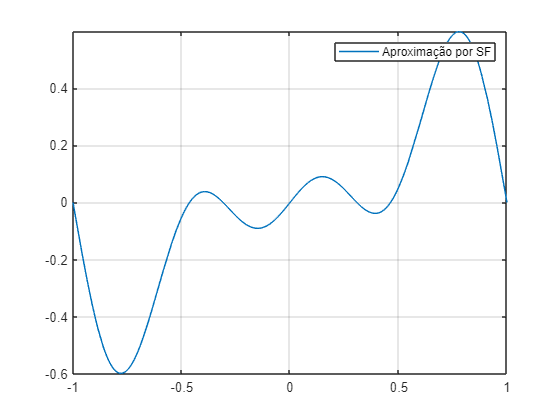


%Aproximação por SF
%7 termos
k = -3:3;
a = 1/T*int(x*exp(-j*k*w*t), t, t0, t0+T);
xx7 = sum(a.*exp(j*k*w*t));
figure
fplot(xx7, [-1 1]);
grid on
legend('Aproximação por SF')

%Relação de potencia
P7 = sum(abs(a).^2);
per = P7/Px;
eval(per) * 100

ans = 61.0113

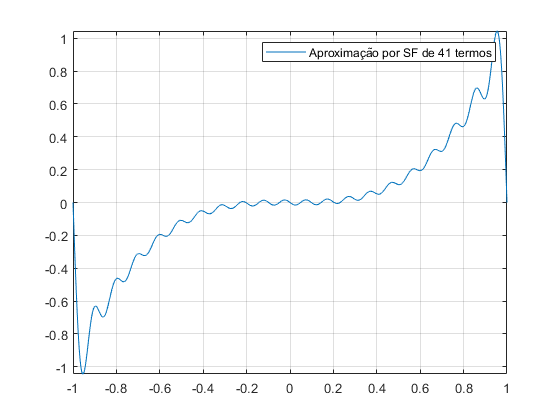

%41 termos
k = -20:20;
a = 1/T*int(x*exp(-j*k*w*t), t, t0, t0+T);
xx41 = sum(a.*exp(j*k*w*t));
figure
fplot(xx41, [-1 1]);
grid on
legend('Aproximação por SF de 41 termos')

%Relação de potencia
P41 = sum(abs(a).^2);
per = P41/Px;
eval(per) * 100

ans = 93.0885

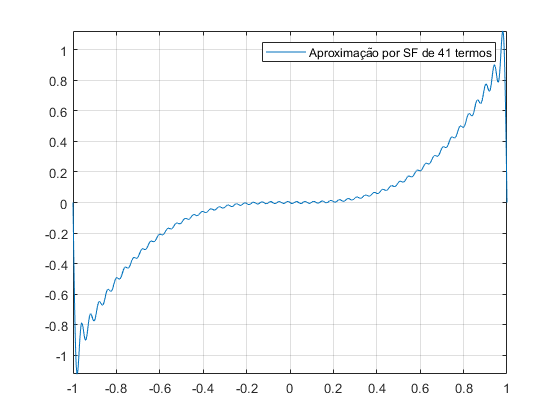

%101 termos
k = -50:50;
a = 1/T*int(x*exp(-j*k*w*t), t, t0, t0+T);
xx101 = sum(a.*exp(j*k*w*t));
figure
fplot(xx101, [-1 1]);
grid on
legend('Aproximação por SF de 41 termos')

%Relação de potencia
P101 = sum(abs(a).^2);
per = P101/Px;
eval(per) * 100

ans = 97.1916

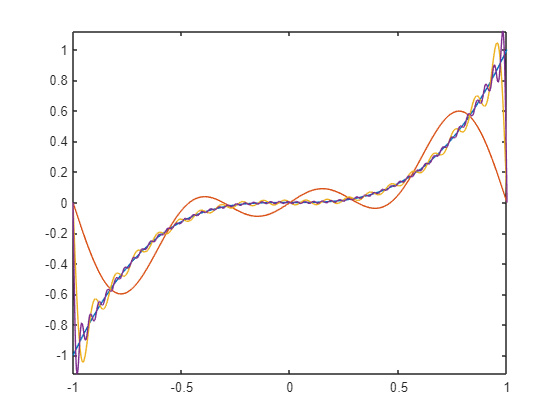


figure 
fplot(x, [-1 1])
hold on
fplot(xx7, [-1 1])
fplot(xx41, [-1 1])
fplot(xx101, [-1 1])